% Experiment Number 2 - Solution of Transcendental Equation
% by Simple Iteration Method - Iteration Based
% Name of Programmer - Sahil Patra
% Roll No - 124MM0055

clc
clear all

% Given function
f = @(x) x.*log10(x) - 1.2;

% Rearranged form x = g(x)
g = @(x) 1.2 ./ log10(x);

ni = input("\n Number of iterations ");
a  = input("\nEnter First Guess ");

% Derivative of g(x) for convergence check
dg = @(x) abs(-1.2 ./ (x .* log(10) .* (log10(x).^2)));

d = dg(a);     % Similar role to your 'd'
c = a;

while d > 1
    fprintf(" The Guess is incorrect (Divergent)\n");
    a = input("\nEnter a new Guess ");
    d = dg(a);
    c = a;
end

 The Guess is incorrect (Divergent)



for i = 1:ni
    c = g(c);   % Simple Iteration formula
end

fprintf('The root is approximately: %.6f\n', c);

The root is approximately: 2.740360


error = abs(f(c));
fprintf("The Error in Calculation after %d iteration = %.6f\n", ni, error);

The Error in Calculation after 100 iteration = 0.000249



% Plotting
x1 = linspace(-10,10,100);
y  = f(x1);

plot(x1, y, "r", LineWidth=2);

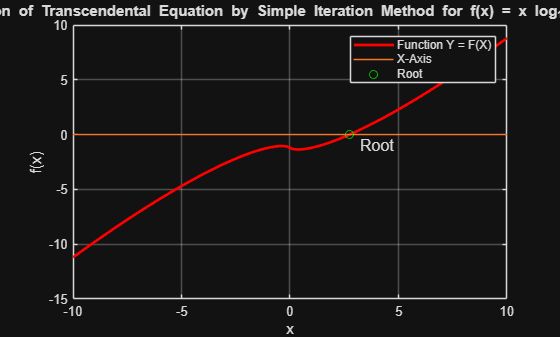

xlabel('x');
ylabel('f(x)');
title('Solution of Transcendental Equation by Simple Iteration Method for f(x) = x log_{10}(x) - 1.2');
grid on;
hold on

y1(1:length(x1)) = 0;
plot(x1, y1);
plot(c, f(c), 'go');
text(c+0.5, f(c)-1, "Root", FontSize=12)

legend("Function Y = F(X)", "X-Axis", "Root")